Question 1

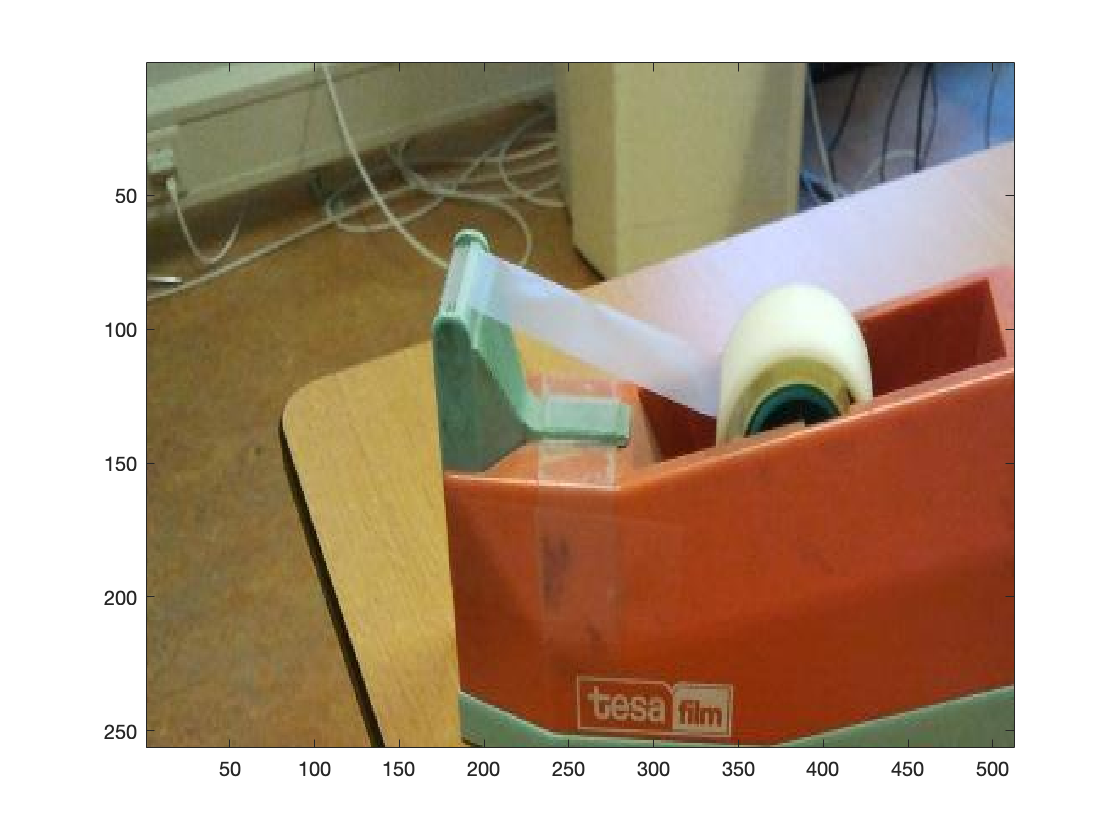

clear
im=imread('imageSIP2014Cropped.jpg');

figure;
% Display something
image(im)


[H,S,I]=rgbtohsi(im)

H =    -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.5488   -2.6180   -2.7330   -2.7330   -2.7330   -2.6180   -2.6180   -2.5736   -2.5736   -2.5115   -2.5115   -2.4146   -2.4146   -2.4146   -2.4146   -2.3754   -2.3754   -2.3754   -2.3754
   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4931   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.4855   -2.5488   -2.6180   -2.7330   -2.7330   -2.6180   -2.6180   -2.5736   -2.5736   -2.5115   -2.5115   -2.5115   -2.4146   -2.4146   -2.4146   -2.4146   -2.3754   -2.3754   -2.3754   -2

S =     0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0851    0.0883    0.0855    0.0855    0.0855    0.0883    0.0883    0.0884    0.0884    0.0922    0.0922    0.0971    0.0971    0.0971    0.0971    0.0980    0.0980    0.0980    0.0980
    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0787    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891    0.0851    0.0883    0.0855    0.0855    0.0883    0.0883    0.0884    0.0884    0.0922    0.0922    0.0922    0.0971    0.0971    0.0971    0.0971    0.0980    0.0980    0.0980    0

I =     0.5046    0.5007    0.4967    0.5007    0.5007    0.5007    0.4928    0.4850    0.4850    0.4850    0.4889    0.4928    0.4967    0.5007    0.5007    0.5007    0.4824    0.4941    0.5020    0.4980    0.4863    0.4784    0.4902    0.4980    0.5059    0.5020    0.4980    0.5020    0.5098    0.5098    0.4941    0.4784    0.5020    0.5033    0.4993    0.5033    0.5059    0.5137    0.5242    0.5281    0.5046    0.5085    0.5072    0.5111    0.5150    0.5190    0.5176    0.5216    0.5412    0.5490
    0.4928    0.4889    0.4850    0.4889    0.4928    0.4928    0.4850    0.4771    0.4850    0.4850    0.4889    0.4889    0.4928    0.4928    0.4967    0.4967    0.4863    0.4941    0.4980    0.5020    0.5020    0.5020    0.5098    0.5137    0.4941    0.4863    0.4902    0.4980    0.5137    0.5216    0.5176    0.5098    0.4980    0.4993    0.4993    0.5059    0.5098    0.5163    0.5242    0.5281    0.5281    0.5359    0.5425    0.5542    0.5660    0.5778    0.5843    0.5882    0.6157    0

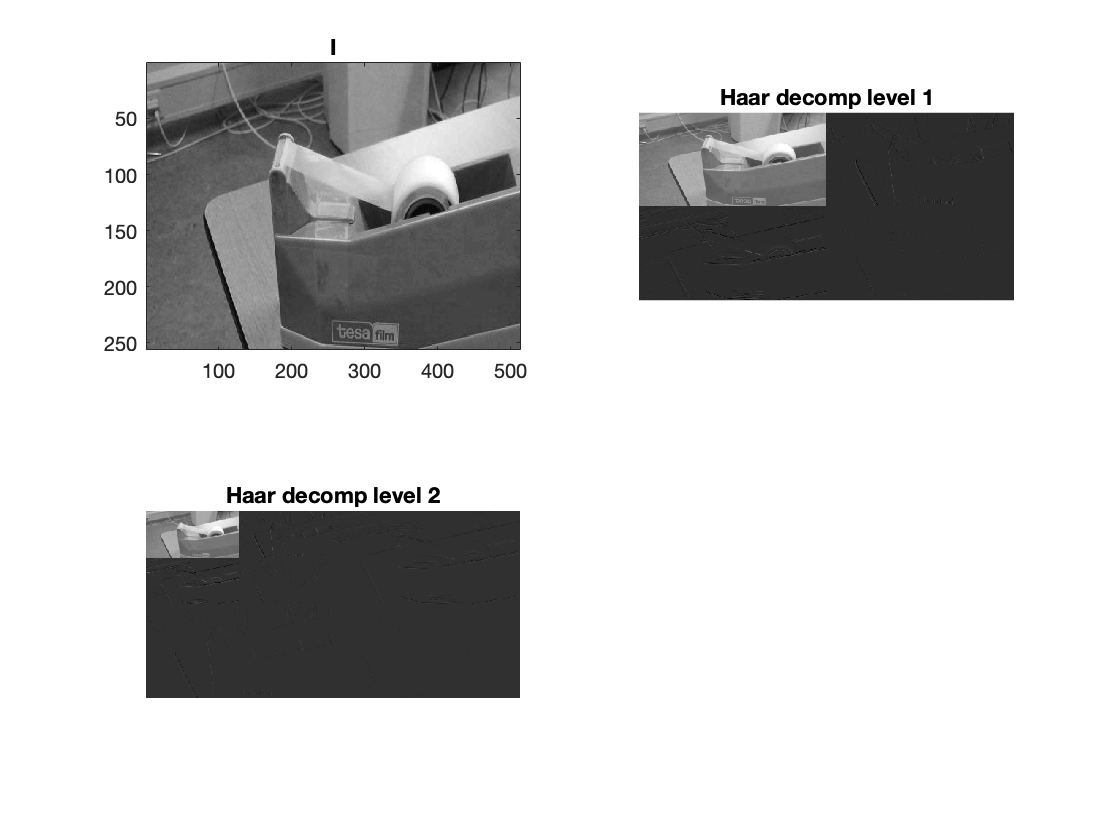


figure
subplot(221)
imagesc(I)
title('I')

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

[b1,h1,v1,d1]=dwlt2(I,c,d);

subplot(222);
imagesc([b1 v1;h1 d1]);
colormap gray
axis image off
title('Haar decomp level 1')

[b2,h2,v2,d2]=dwlt2(b1,c,d);
subplot(223);
imagesc([[b2 v2;h2 d2] h1; v1 d1]);
axis image off
title('Haar decomp level 2')

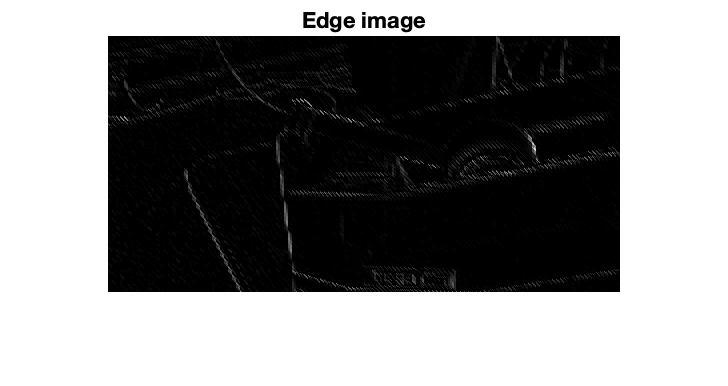


bs=zeros(size(b2));
% R2=abs(idwlt2(bs,h2,v2,d2,c,d));
% edge=abs(idwlt2(R2,h1,v1,d1,c,d));
% 
% subplot(224)
% imagesc(edge)
% colormap gray
% axis image off
% title ('Edge image')

alfa=1.0;

tau1=thresholding(alfa,h1,v1,d1);
tau2=thresholding(alfa,h2,v2,d2);

R2=idwlt2(bs,h2.*(abs(h2)>tau2),v2.*(abs(v2)>tau2),d2.*(abs(d2)>tau2),c,d);
R1=idwlt2(R2,h1.*(abs(h1)>tau1),v1.*(abs(v1)>tau1),d1.*(abs(d1)>tau1),c,d);

figure;
imshow(R1);
colormap gray
axis image off
title ('Edge image')

Question 3

clear
load('SignalExercise4.mat');

load('filterExercise4.mat')

fs=44100;
f1=5000;

a) Yes 

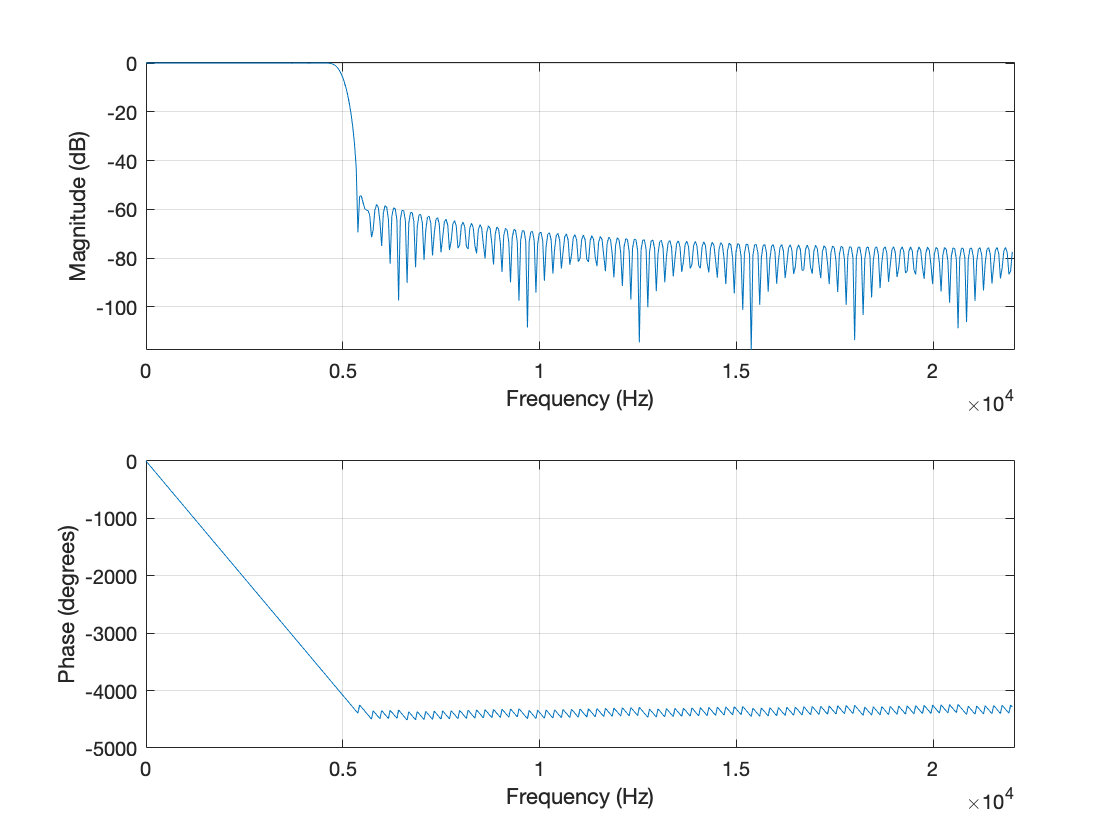

freqz(B,1,[],fs)

b)

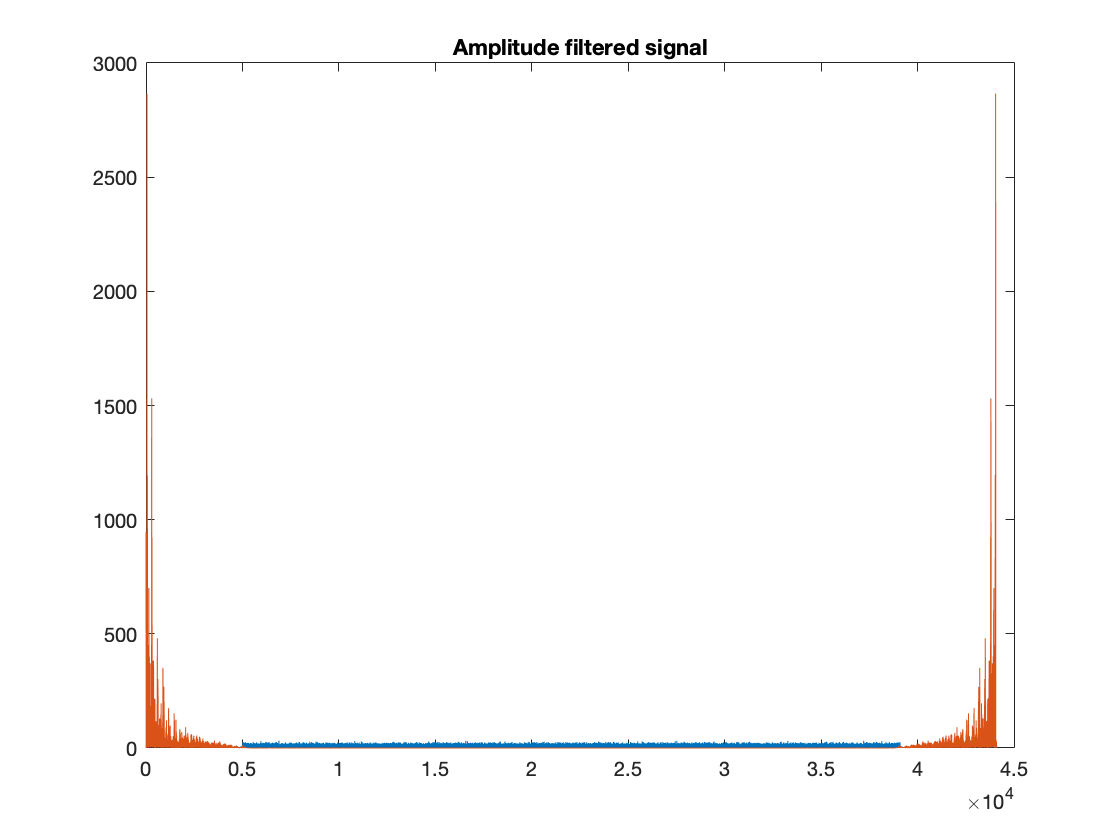

t = ((0:length(y)-1)*fs)./length(y);
y2=filter(B,1,y);

figure;

plot(t,abs(fft(y)));
title('Amplitude original signal');
hold on

plot(t,abs(fft(y2)));
title('Amplitude filtered signal');

c)

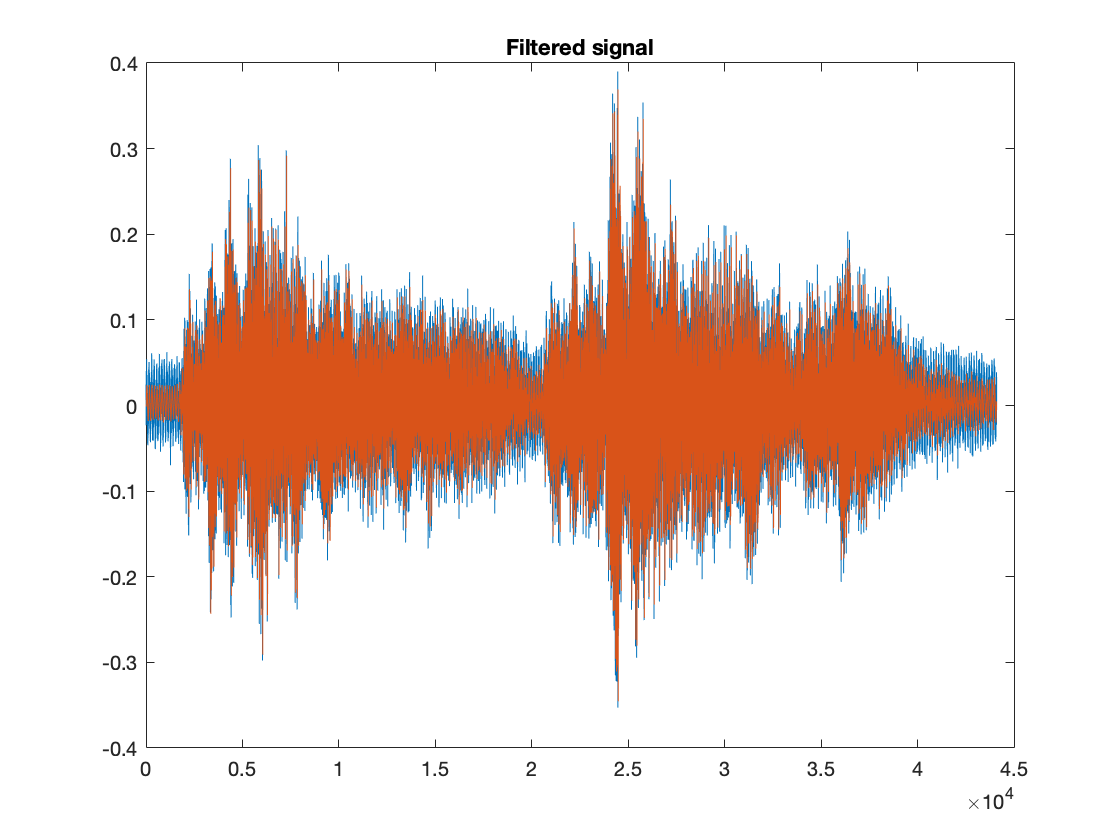

figure;
plot(t,y) 
title('Original signal');
hold on

plot(t,y2) 
title('Filtered signal');

d)

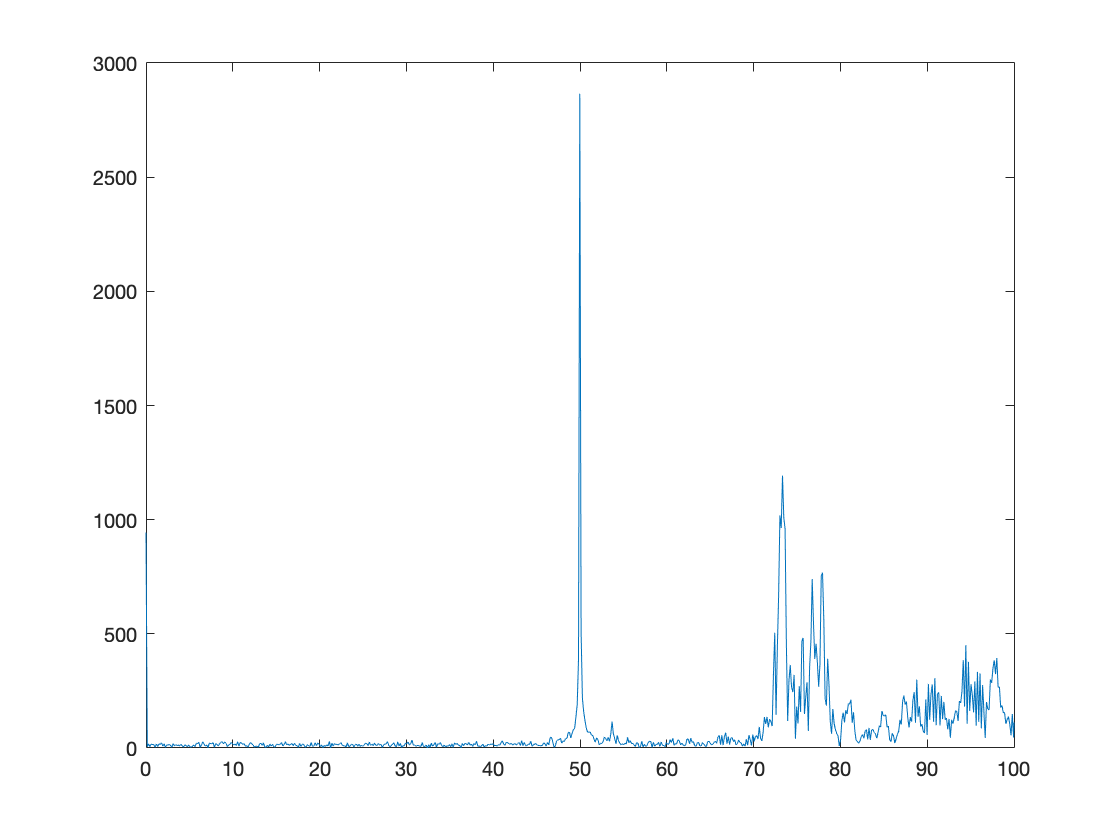

figure
plot(t,abs(fft(y2)));
axis([0 100 0 3000])

e)

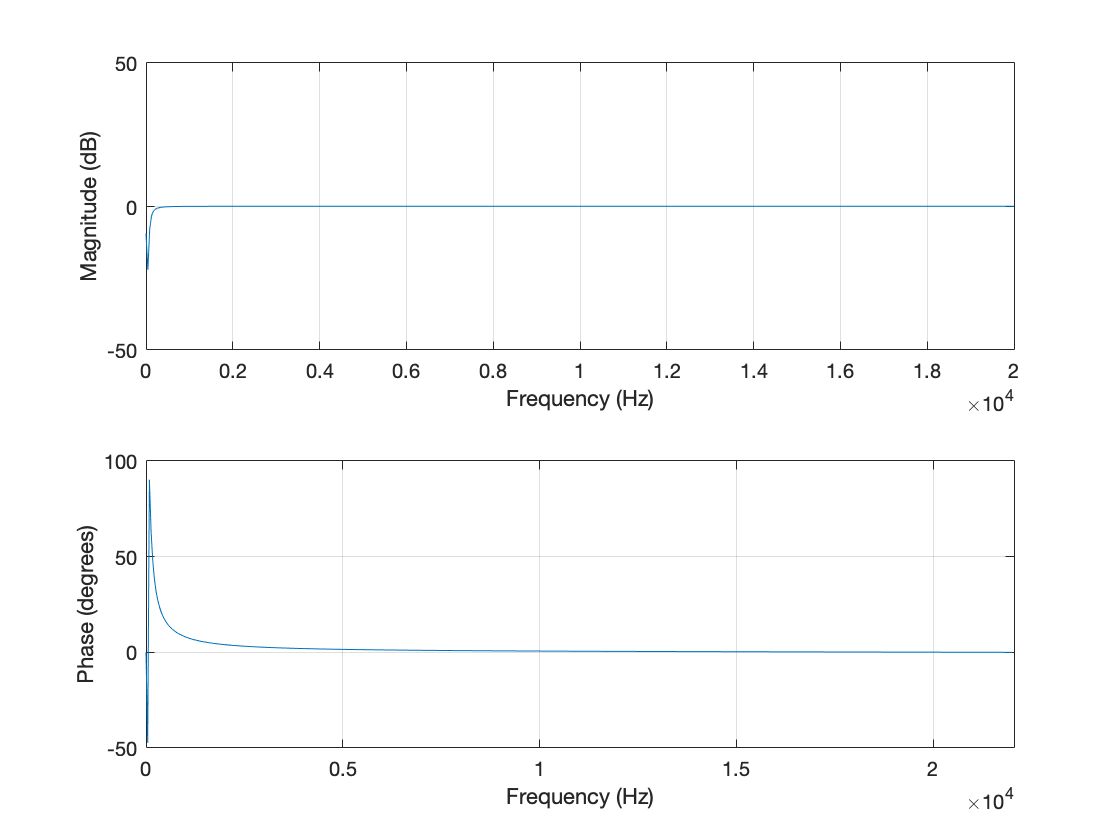

f=50;
nf=f/fs;

omega2=2*pi*nf;

z1=exp(1i*omega2);
z2=exp(-1i*omega2);

%if we dont consider poles just put a=1
p1=0.99*exp(1i*omega2);
p2=0.99*exp(-1i*omega2);

a2=[1,-(p1+p2),p1*p2];
b2=[1,-(z1+z2),z1*z2];

figure,
freqz(b2,a2,[],fs)
axis([0 20000 -50 50])

f)

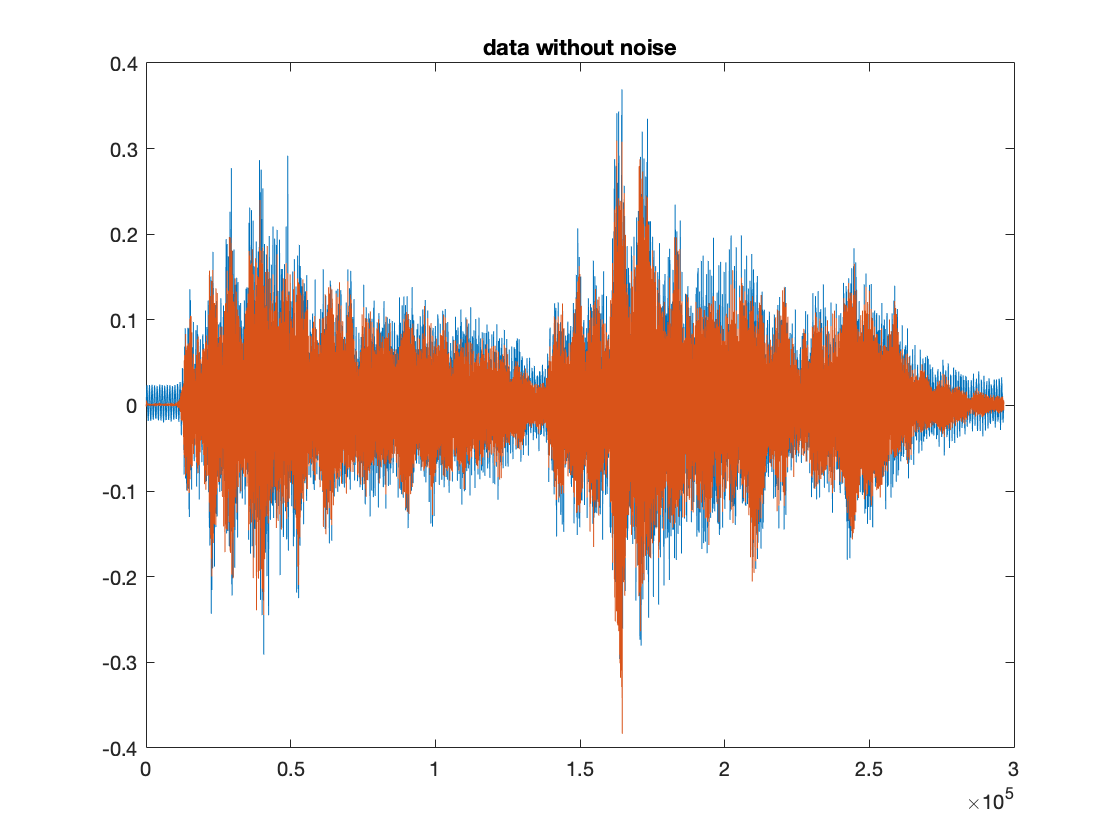

y_filt2=filter(b2,a2,y2);

figure
plot([y2,y_filt2]) 
title('data without noise')

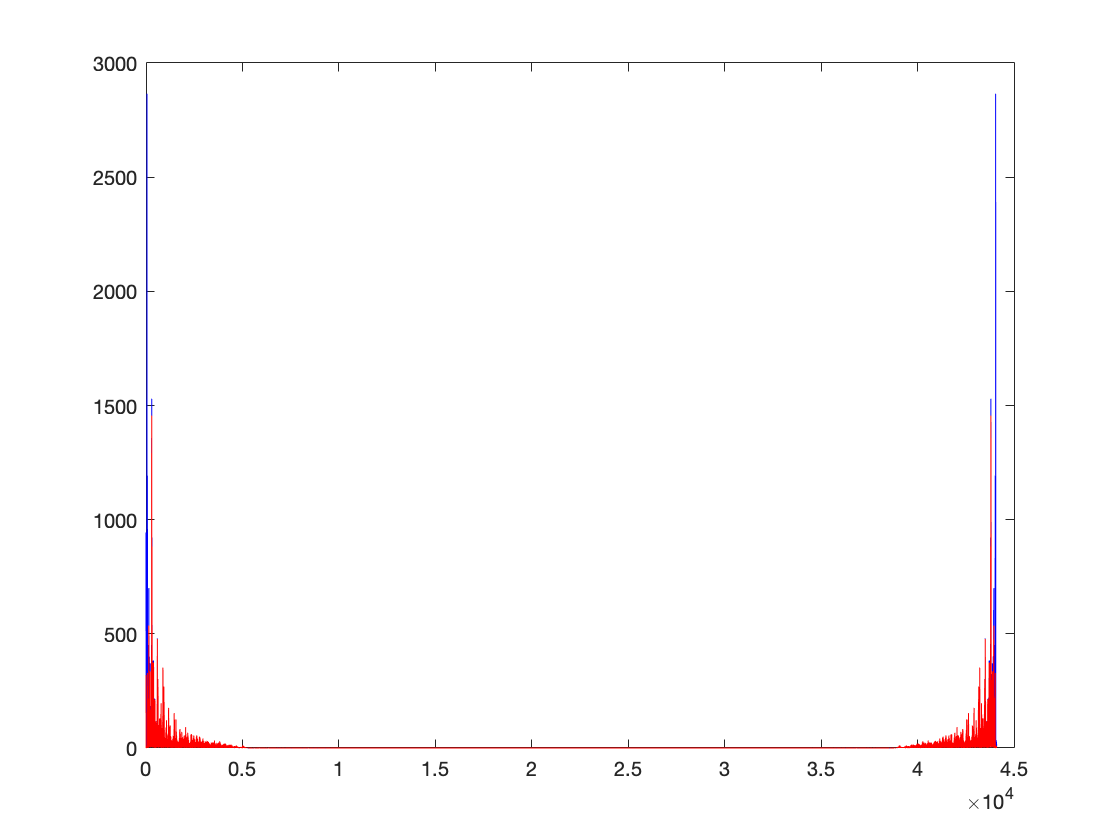


figure,
plot(t,abs(fft(y2)),'b',t,abs(fft(y_filt2)),'r');

Question 4

clear
load('SignalExercise5.mat')

size(X);
%data=data';

figure
plot3(X(1,:),X(2,:),X(3,:),'.')
% % 
% [m, n] = size(X);
% 
% mx=mean(X,1);
% 
% X0=X-(mx'*ones(1,m))';

X0=bsxfun(@minus, X , mean(X,1));
%data_centered=data_centered'
%X0=X0'

figure
plot3(X0(1,:),X0(2,:),X0(3,:),'.')

N = size(X,2);

%economjic side function, makes sure its 
%the right order and right size
[U, S, V] = svd(X0,'econ');
%X=U*S*V';

A=(U*S)/(sqrt(N-1));
Z=sqrt(N-1)*V';

abs(A(:,1))
%second variable

cumvar=cumsum(S.^2)/sum(S.^2);
%i can plot cumvar and read if off
figure;
plot(cumvar)
%or do it automatically
numberofcomponets95prc = find(cumvar>0.95,1,'first')
%one principal component
X95=A(:,1)*pinv(A(:,1))*X0;

%add the mean back
data95=bsxfun(@plus,X95,mean(X,1)) 

figure
plot3(X(1,:),X(2,:),X(3,:),'.')
hold on
plot3(data95(1,:),data95(2,:),data95(3,:),'.')


Question 5 p229

clear

%energy_cons=sum(filter.^2)=1

h2=0.35*sqrt(2)

h2 = 0.4950


% [h2,h3]'==c*[-h1,h0]';
% h0^2+h1^2==1/(1+c^2);
% h0-h1+h2-h3==0;
% h0-h1-c*h1-c*h0==0;
% h1==((1-c)/(1+c))*h0;
% h2==-c*(1-c)/(sqrt(2)*(1+c^2));
syms c
px=solve(h2==-c*(1-c)/(sqrt(2)*(1+c^2)),c)

$$px = \left(\begin{array}{c} \frac{5}{3}-\frac{\sqrt{46}}{3}\\ \frac{\sqrt{46}}{3}+\frac{5}{3} \end{array}\right)$$


c=px(2)

$$c = \frac{\sqrt{46}}{3}+\frac{5}{3}$$

c=double(c)

c = 3.9274


h00=(1+c)/(sqrt(2)*(1+c^2));
h11=(1-c)/(sqrt(2)*(1+c^2));
h33=(c*(1+c))/(sqrt(2)*(1+c^2))

h33 = 0.8331

% y=zeros(1,power);
h=[h00,h11,h2,h33]

h =     0.2121   -0.1260    0.4950    0.8331




% syms h0 h1 h3
% 
% h0+h1+h2+h3==sqrt(2);
% h0*h2+h1*h3==0;
% h0-h1+h2-h3==0

h0=h2+(sqrt(2)-2*h2)/2

h0 = 0.7071


p=[-1,0.3*sqrt(2)/2,h2.^2+0.3*sqrt(2)/2*h2]

p =    -1.0000    0.2121    0.3500


r=roots(p)

r =     0.7071
   -0.4950


h3=r(1);
h1=(-h0*h2)/h3

% p=[-1,0.2121,0.35]
% r=roots(p)
% h3=r(1);

h1 = -0.1167

%h0=h2+h1+h3

h_final=[h0,h1,h2,h3]

h_final =     0.7071   -0.1167    0.4950    0.7071


Question 6

clear
load('data2014Question6.mat')

v=val

v =    -36   -75   -53   -44   -34   -44   -21     3   -35   -26   -18   -28    14    44    36    20   -24   -33   -39   -51   -14   -21   -36   -26     3    -2     8    -7   -25   -30   -42   -42    16    13   -31   -21    -4   -26   -38     3    15     3    18    -4   -38   -14   -23     1    52    11


n=length(v);
%fl=dbwavf('db4')
fl=dbfilter(4)


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 400 (the default value).



fl =    -0.0138    0.0686    0.4580    0.5840    0.1270   -0.1684   -0.0624    0.0103


fh=fliplr(fl).*[1 -1 1 -1 1 -1 1 -1]

fh =     0.0103    0.0624   -0.1684   -0.1270    0.5840   -0.4580    0.0686    0.0138



[a1,b1]=discreteWaveletTransform(v,fl,fh);
[a2,b2]=discreteWaveletTransform(a1,fl,fh);
[a3,b3]=discreteWaveletTransform(a2,fl,fh);
[a4,b4]=discreteWaveletTransform(a3,fl,fh);

N=length(b1)+length(b3)+length(b3);

sigma=mad(b1,1)/0.6745;
lambda=sigma*sqrt(2*log(N));

b1s=softThresholding(b1,lambda);
b2s=softThresholding(b2,lambda);
b3s=softThresholding(b3,lambda);
b4s=softThresholding(b4,lambda);

a33 = invDaubechies1D(a4,b4s,fl,fh);
a22 = invDaubechies1D(a33,b3s,fl,fh);
a11 = invDaubechies1D(a22,b2s,fl,fh);
rec_sig = invDaubechies1D(a11,b1s,fl,fh);

rec_sig=rec_sig(1:n);

rec_sig=rec_sig'

rec_sig =   -13.8883  -49.8750  -71.4075  -74.9091  -71.5133  -72.3937  -64.9056  -52.7432  -39.7172  -32.8217  -23.9664  -13.2278   -2.0703   13.9016   19.8184    5.9885   -8.0263  -22.9637  -34.3522  -44.3743  -48.1670  -48.2757  -44.7553  -43.4263  -38.2912  -31.7728  -24.7827  -20.7888  -18.2042  -22.6878  -21.6501   -8.4864   -1.5326  -10.8032  -16.1790  -14.1817  -11.9989  -11.1951   -9.7638   -9.2159   -6.6061    0.7523    5.4301    5.1107    2.2005   -7.7059   -9.0379   12.1586   23.1527   11.7486


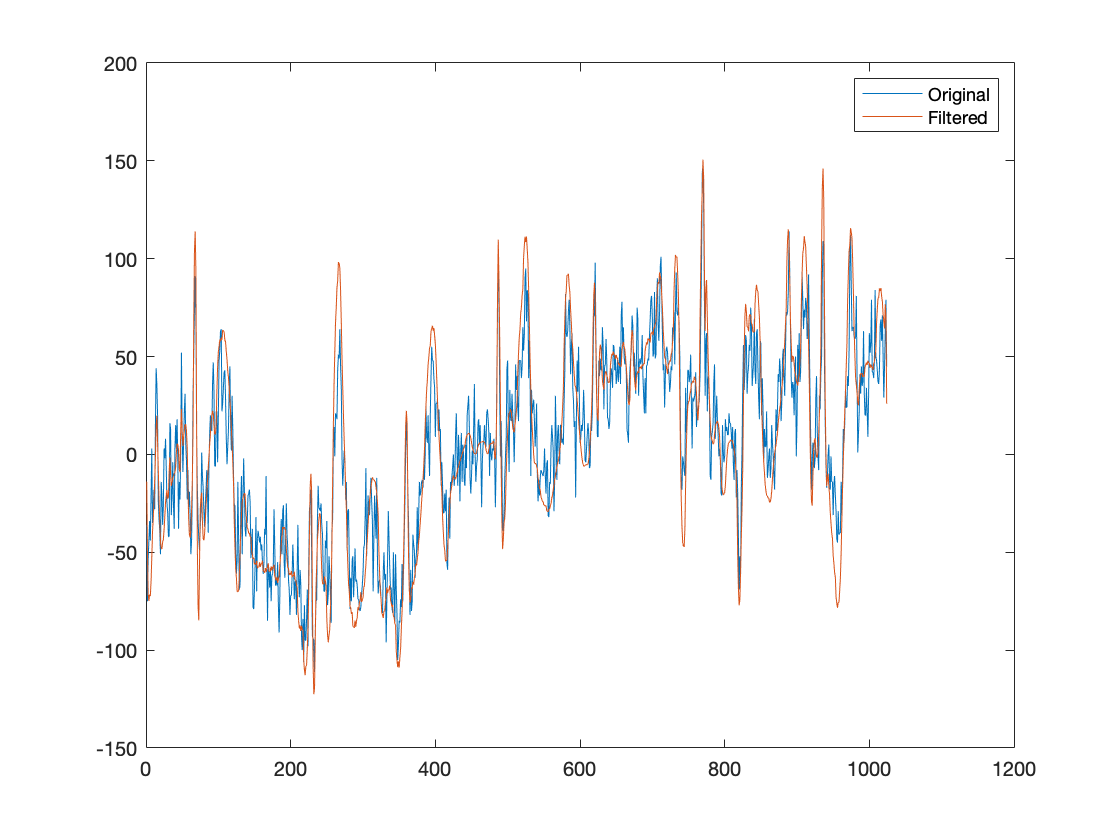

figure
plot(val)
hold on
plot(rec_sig)
legend('Original','Filtered')